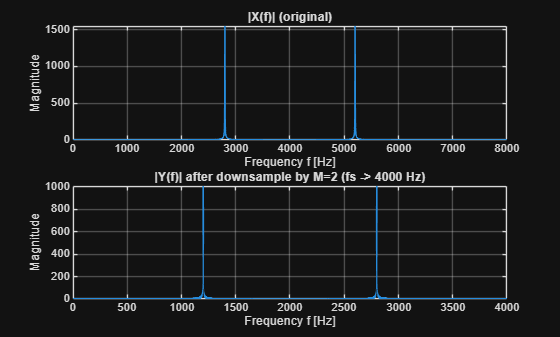

%% Part A: Downsampling by 2 (real frequencies, Hz)
clear; close all; clc;

%% Parameters (real units)
fs = 8000;                   % sampling rate [Hz]
Ts = 1/fs;
N  = 4096;                   % FFT length (smooth spectra)
t  = (0:N-1)*Ts;

%% Pick a tone that will alias after /2 (0.35*fs -> 2800 Hz for fs=8 kHz)
f0 = 0.35 * fs;                % [Hz]
x  = cos(2*pi*f0*t);

%% Downsample by M=2
M    = 2;
y    = x(1:M:end);
fs_y = fs/M;                 % new sampling rate [Hz]
Ty   = 1/fs_y;

%% Zero-pad y to length N for equal-length FFT comparison
yZ = zeros(1,N);
yZ(1:length(y)) = y;

%% Compute spectra
X  = fft(x, N);
Y  = fft(yZ, N);
fx = (0:N-1)*(fs/N);
fy = (0:N-1)*(fs_y/N);

%% Plot spectra
figure;
subplot(2,1,1);
plot(fx, abs(X), 'LineWidth',1.2); grid on;
title('|X(f)| (original)');
xlabel('Frequency f [Hz]'); ylabel('Magnitude');

subplot(2,1,2);
plot(fy, abs(Y), 'LineWidth',1.2); grid on;
title(sprintf('|Y(f)| after downsample by M=%d (fs -> %.0f Hz)', M, fs_y));
xlabel('Frequency f [Hz]'); ylabel('Magnitude');

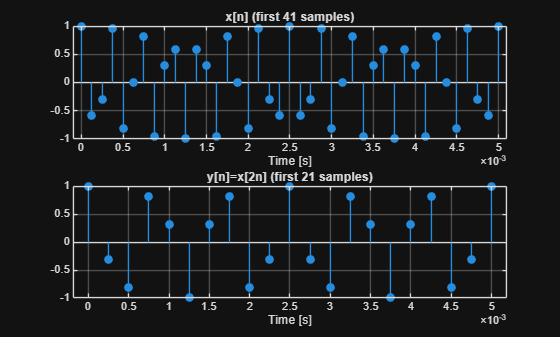


%% Time-domain view (first few samples)
figure;
subplot(2,1,1);
stem(t(1:41), x(1:41), 'filled'); grid on;
title('x[n] (first 41 samples)'); xlabel('Time [s]');

subplot(2,1,2);
ty = (0:length(y)-1)*Ty;
stem(ty(1:21), y(1:21), 'filled'); grid on;
title('y[n]=x[2n] (first 21 samples)'); xlabel('Time [s]');

Questions for students:

Q1: What is the apparent tone frequency after downsampling (in Hz)?

1200 Hz: original tone is 2800 Hz. New sample rate is 4000 Hz, so it aliases to ∣2800−1⋅4000∣=1200 Hz

Q2: Why does |Y(f)| look compressed/overlapped compared to |X(f)|?

Because the sampling rate is halved, the frequency axis shrinks so the spectrum is plotted over a tighter range and any energy above the new Nyquist folds (aliases) back into baseband

Q3: What bandlimit on |X(f)| avoids aliasing for M=2?

2000 Hz

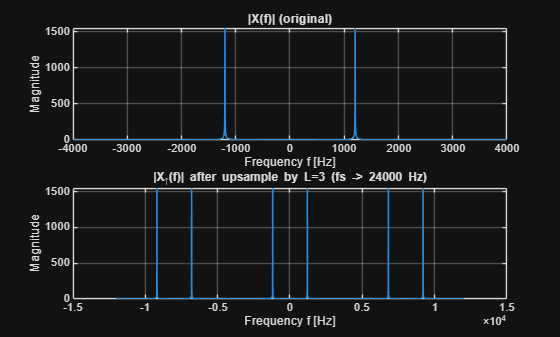

%% Part B: Upsampling by 3 (real frequencies, Hz)
clear; close all; clc;

%% Parameters (real units)
fs = 8000;                   % original sampling rate [Hz]
Ts = 1/fs;
N  = 4096;
t  = (0:N-1)*Ts;

%% Tone that shows clear images after upsampling
f0 = 0.15*fs;                % e.g., 1200 Hz for fs=8 kHz
x  = cos(2*pi*f0*t);

%% Upsample by L=3 (zero insertion)
L  = 3;
xu = zeros(1, L*length(x));
xu(1:L:end) = x;

fs_u = L*fs;                 % new sampling rate [Hz]
Tu   = 1/fs_u;
Nu   = L*N;                  % pick FFT length ~ multiple of L

%% Spectra and frequency axes in Hz
X  = fftshift(fft(x,  N));
Xu = fftshift(fft(xu, Nu));
fx = linspace(-fs/2,  fs/2,  N);
fu = linspace(-fs_u/2, fs_u/2, Nu);

%% Plot spectra: images appear every fs
figure;
subplot(2,1,1);
plot(fx, abs(X), 'LineWidth',1.2); grid on;
title('|X(f)| (original)');
xlabel('Frequency f [Hz]'); ylabel('Magnitude');

subplot(2,1,2);
plot(fu, abs(Xu), 'LineWidth',1.2); grid on;
title(sprintf('|X_{\\uparrow}(f)| after upsample by L=%d (fs -> %.0f Hz)', L, fs_u));
xlabel('Frequency f [Hz]'); ylabel('Magnitude');

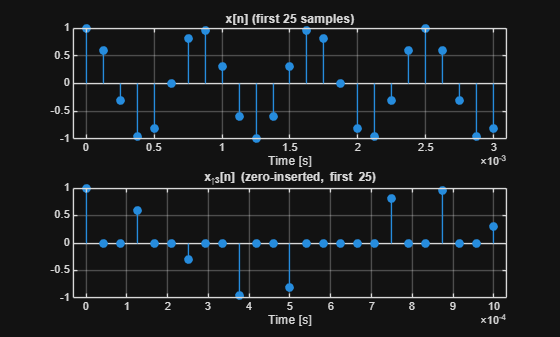


%% Time-domain view (first few samples)
figure;
subplot(2,1,1);
stem(t(1:25), x(1:25), 'filled'); grid on;
title('x[n] (first 25 samples)'); xlabel('Time [s]');

subplot(2,1,2);
tu = (0:length(xu)-1)*Tu;
stem(tu(1:25), xu(1:25), 'filled'); grid on;
title(sprintf('x_{\\uparrow%d}[n] (zero-inserted, first 25)', L));
xlabel('Time [s]');

Questions for students:

Q4: How many spectral images appear in [-fs_u/2, fs_u/2]?

3 Images, It is equal to L.

Q5: Around which Hz do the images center (hint: multiples of fs_u/L = fs)?

Interger multiples 

Q6: Describe (in words) a simple low-pass you would apply to remove the images.

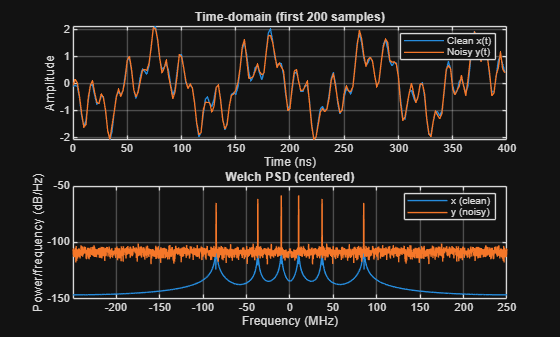

close all; clear; clc;

%% Parameters
Fs = 500e6;              % Sample rate (Hz) > 2*100 MHz
T  = 20e-6;              % Signal duration (seconds)
N  = round(Fs*T);        % Number of samples
t  = (0:N-1).' / Fs;     % Time vector (column)

% All frequencies are inside 0–100 MHz, so the sum will be band-limited by construction.

%% Choose a few tones inside 0–100 MHz
f   = [10e6, 37e6, 85e6];      % Hz
A   = [1.0, 0.7, 0.5];          % amplitudes
phi = 2*pi*rand(size(f));       % random phases (optional)

% 'x' is a deterministic real signal made of three cosines.
% It has some power Px = mean(x.^2);

%% Real band-limited signal (sum of cosines)
x = A(1)*cos(2*pi*f(1)*t + phi(1)) ...
  + A(2)*cos(2*pi*f(2)*t + phi(2)) ...
  + A(3)*cos(2*pi*f(3)*t + phi(3));

%% --- Add noise (pick ONE of the following blocks) ---

% (A) Set a target SNR in dB relative to the signal power
snr_dB = 20;                 % e.g., 20 dB SNR
Px = mean(x.^2);             % signal power
Pn = Px / 10^(snr_dB/10);    % noise power
noise = sqrt(Pn) * randn(size(x));  % AWGN (real)

y = x + noise;               % noisy signal

% (B) OR: Set noise standard deviation directly
% sigma = 0.05;                % try 0.01 ... 0.1
% y = x + sigma*randn(size(x));

%% Time plot: just the first 200 samples (fast to interpret at these rates)
% Convert to ns for readable axes (/1e-9).
% pwelch (Welch's method) estimates the power spectral density
% to verify band-limit and see the noise floor rise.
% 4096 FFT points, 2048 overlap is a common default balance.
% 'centered' shows negative and positive frequencies around 0 Hz.

%% Quick looks
figure;
subplot(2,1,1);
plot(t(1:200)/1e-9, x(1:200), 'LineWidth', 1); hold on;
plot(t(1:200)/1e-9, y(1:200), 'LineWidth', 1);
xlabel('Time (ns)'); ylabel('Amplitude');
legend('Clean x(t)', 'Noisy y(t)');
grid on;
title('Time-domain (first 200 samples)');

subplot(2,1,2);
pwelch(x, 4096, 2048, 4096, Fs, 'centered'); hold on;
pwelch(y, 4096, 2048, 4096, Fs, 'centered');
legend('x (clean)', 'y (noisy)');
title('Welch PSD (centered)'); grid on;

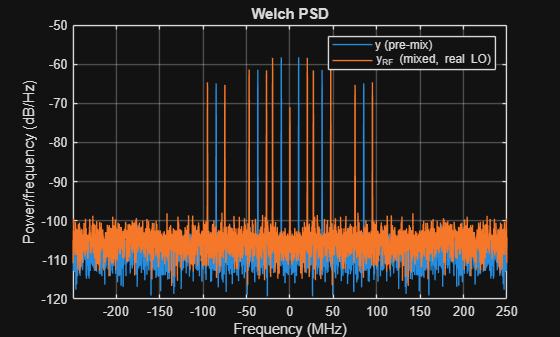

% What happens to your tones (10, 37, 85 MHz)?
% Multiplying by cos(10 MHz) makes lines at:
%
%   'Difference' |f - fLO|:  0, 27, 75 MHz
%   'Sum'        |f + fLO|: 20, 47, 95 MHz
% (Each gets ~1/2 amplitude unless you scale by 2 for "unity" conversion gain.)

fLO = 10e6;                 % LO = 10 MHz

% Real mixing (double-sideband): y_RF has components at f ± fLO
y_RF = 2 * y .* cos(2*pi*fLO*t);     % 2x for ~0 dB conversion gain


% Inspect spectrum
figure;
pwelch(y,    4096, 2048, 4096, Fs, 'centered'); hold on;
pwelch(y_RF, 4096, 2048, 4096, Fs, 'centered');
legend('y (pre-mix)','y_{RF} (mixed, real LO)');
grid on; 
title('Welch PSD');

%% 2) Narrow low-pass to keep only the DC-centered tone
% Pick cutoff well below the next spur (27 MHz) so it gets rejected.
Fc = 2e6;                       % 2 MHz passband (adjust as desired)
z_lp  = lowpass(y_RF, Fc, Fs);     % removes everything beyond ~2 MHz

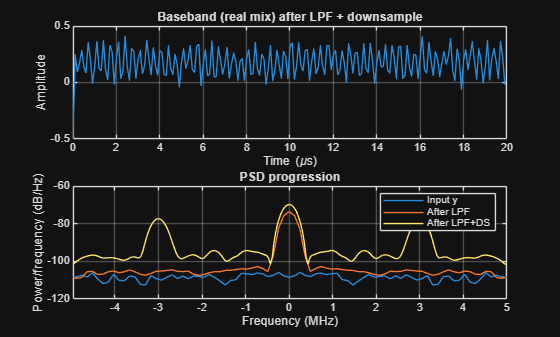

%% 3) Downsample aggressively (keep Nyquist comfortably above Fc)
M = 50;                           % decimate by 50: 500e6 -> 10e6
Fs_ds = Fs / M;                   % 10 MHz sample rate
z_ds = downsample(z_lp, M);
t_ds = (0:numel(z_ds)-1).' / Fs_ds;

%% Quick look
figure;
subplot(2,1,1);
ns = min(5000, numel(z_ds));
plot(t_ds(1:ns)*1e6, z_ds(1:ns), 'LineWidth', 1);
xlabel('Time (\mus)'); ylabel('Amplitude'); grid on;
title('Baseband (real mix) after LPF + downsample');

subplot(2,1,2);
pwelch(y,      [], [], [], Fs,    'centered'); hold on;
pwelch(z_lp,   [], [], [], Fs,    'centered');
pwelch(z_ds,   [], [], [], Fs_ds, 'centered');
legend('Input y','After LPF','After LPF+DS');
title('PSD progression'); grid on;

## Presentation Plots

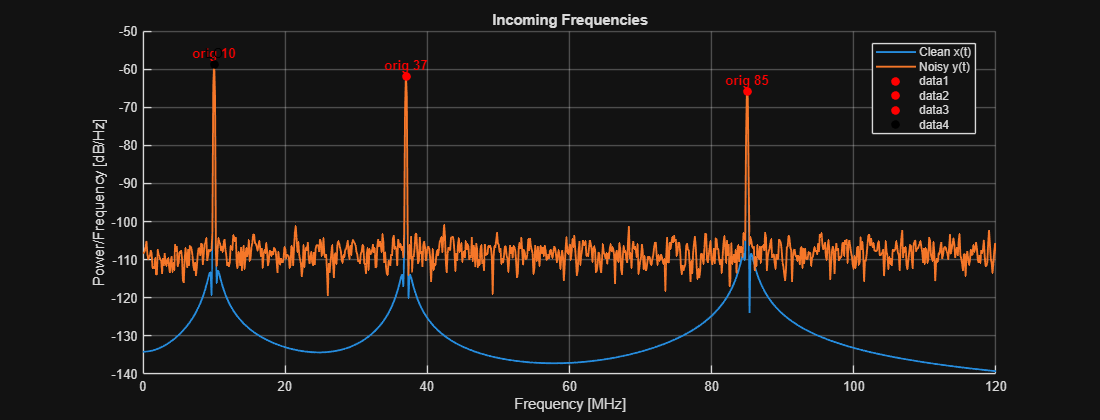


%% 1) Incoming spectrum (clean + noisy)
[Px, fx] = pwelch(x, 4096, 2048, 4096, Fs, 'centered');
[Py, fy] = pwelch(y, 4096, 2048, 4096, Fs, 'centered');
Px_dB = 10*log10(Px);  
Py_dB = 10*log10(Py);

figure('Position',[100 100 1100 420]);
hold on; grid on;
plot(fx/1e6, Px_dB, 'LineWidth',1.4);
plot(fy/1e6, Py_dB, 'LineWidth',1.4);
xlim([0 120]);
xlabel('Frequency [MHz]'); ylabel('Power/Frequency [dB/Hz]');
title('Incoming Frequencies');
legend({'Clean x(t)','Noisy y(t)'},'Location','best');

% Labels: original tones (red) + LO (black)
for k = 1:numel(f)
    freq_MHz = f(k)/1e6;
    y_val = interp1(fy/1e6, Py_dB, freq_MHz, 'linear', 'extrap');
    plot(freq_MHz, y_val, 'ro', 'MarkerFaceColor','r');
    text(freq_MHz, y_val+3, sprintf('orig %.0f', freq_MHz), ...
        'Color','r','FontWeight','bold','HorizontalAlignment','center');
end
y_val_LO = interp1(fy/1e6, Py_dB, fLO/1e6, 'linear', 'extrap');
plot(fLO/1e6, y_val_LO, 'ko', 'MarkerFaceColor','k');
text(fLO/1e6, y_val_LO+3, 'LO', 'Color','k','FontWeight','bold', ...
    'HorizontalAlignment','center');

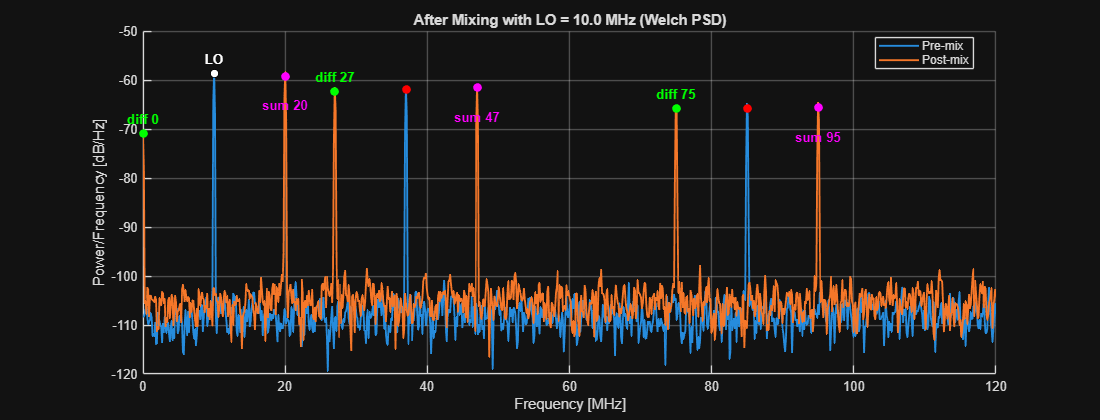


%% 2) After mixing (show sum & difference)
[Ppre, fpre] = deal(Py, fy);
[Pm, fm]     = pwelch(y_RF, 4096, 2048, 4096, Fs, 'centered');
Ppre_dB = 10*log10(Ppre);
Pm_dB   = 10*log10(Pm);
figure('Position',[100 100 1100 420]);
hold on; grid on;
plot(fpre/1e6, Ppre_dB, 'LineWidth',1.4);
plot(fm/1e6,   Pm_dB,   'LineWidth',1.4);
xlim([0 120]);
xlabel('Frequency [MHz]'); ylabel('Power/Frequency [dB/Hz]');
title(sprintf('After Mixing with LO = %.1f MHz (Welch PSD)', fLO/1e6));
legend({'Pre-mix','Post-mix'},'Location','best');
lgd = legend('show');
lgd.AutoUpdate = 'off';

% Labels: difference (green), sum (magenta), originals (red), LO (black)
f_diff = abs(f - fLO);  % Difference tones
f_sum  = f + fLO;       % Sum tones
for k = 1:numel(f)
    % Difference
    diff_MHz = f_diff(k)/1e6;
    y_diff = interp1(fm/1e6, Pm_dB, diff_MHz, 'linear', 'extrap');
    plot(diff_MHz, y_diff, 'go', 'MarkerFaceColor','g');
    text(diff_MHz, y_diff+3, sprintf('diff %.0f', diff_MHz), ...
        'Color','g','FontWeight','bold','HorizontalAlignment','center');
    % Sum
    sum_MHz = f_sum(k)/1e6;
    y_sum = interp1(fm/1e6, Pm_dB, sum_MHz, 'linear', 'extrap');
    plot(sum_MHz, y_sum, 'mo', 'MarkerFaceColor','m');
    text(sum_MHz, y_sum-6, sprintf('sum %.0f', sum_MHz), ...
        'Color','m','FontWeight','bold','HorizontalAlignment','center');
    % Original
    orig_MHz = f(k)/1e6;
    y_orig = interp1(fpre/1e6, Ppre_dB, orig_MHz, 'linear', 'extrap');
    plot(orig_MHz, y_orig, 'ro', 'MarkerFaceColor','r');
end

% Mark LO 
plot(fLO/1e6, y_val_LO, 'ko', 'MarkerFaceColor','w');
text(fLO/1e6, y_val_LO+3, 'LO', 'Color','w','FontWeight','bold', ...
    'HorizontalAlignment','center');

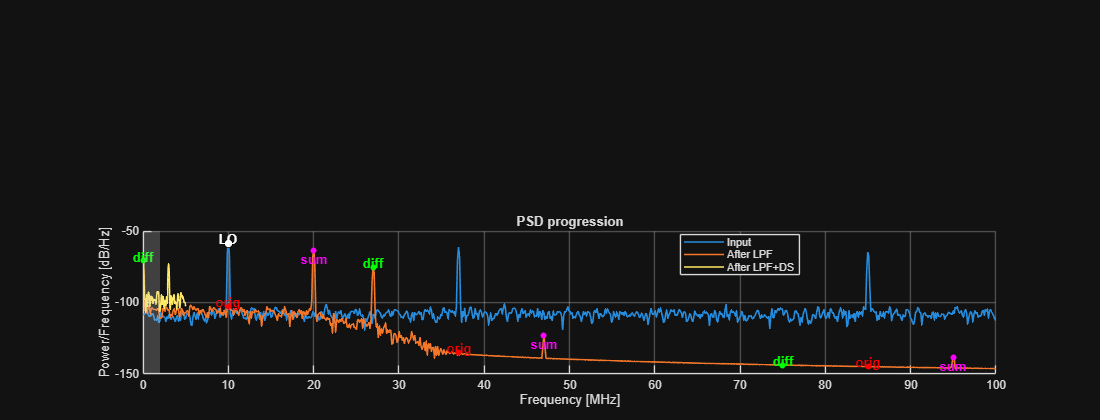



%% 3). PSD progression 
subplot(2,1,2); cla; hold on; grid on;

%  Welch parameters (safe for short z_ds)
w_y   = 4096; o_y   = 2048; nfft_y   = 4096; 
w_lp  = 4096; o_lp  = 2048; nfft_lp  = 4096; 
w_ds  = min(128, numel(z_ds)); o_ds = floor(w_ds/2); 
nfft_ds = max(256, 2^nextpow2(w_ds));

% Compute PSDs 
[Ppre, f_y]  = pwelch(y,    hamming(w_y),  o_y,  nfft_y,  Fs,    'centered');
[Plp,  f_lp] = pwelch(z_lp, hamming(w_lp), o_lp, nfft_lp, Fs,    'centered');
[Pds,  f_ds] = pwelch(z_ds, hamming(w_ds), o_ds, nfft_ds, Fs_ds, 'centered');
Ppre_dB = 10*log10(Ppre); 
Plp_dB  = 10*log10(Plp); 
Pds_dB  = 10*log10(Pds);

% Plot three stages 
plot(f_y /1e6, Ppre_dB, 'LineWidth', 1.2);   % Input
plot(f_lp/1e6, Plp_dB,  'LineWidth', 1.2);   % After LPF
plot(f_ds/1e6, Pds_dB,  'LineWidth', 1.2);   % After LPF+DS
legend({'Input','After LPF','After LPF+DS'}, 'Location','best');
lgd = legend('show');
lgd.AutoUpdate = 'off';
xlabel('Frequency [MHz]'); ylabel('Power/Frequency [dB/Hz]');
title('PSD progression');
xlim([0 100]);

% Mark key tones 
for k = 1:numel(f)
    diff_MHz = abs(f(k)-fLO)/1e6; 
    sum_MHz  = (f(k)+fLO)/1e6;
    orig_MHz = f(k)/1e6;

    % Use LPF PSD for marker height
    y_diff = interp1(f_lp/1e6, Plp_dB, diff_MHz, 'linear','extrap');
    y_sum  = interp1(f_lp/1e6, Plp_dB, sum_MHz,  'linear','extrap');
    y_orig = interp1(f_lp/1e6, Plp_dB, orig_MHz, 'linear','extrap');

    % Plot simple dots with small text
    plot(orig_MHz, y_orig, 'ro', 'MarkerFaceColor','r', 'MarkerSize',4);
    plot(diff_MHz, y_diff, 'go', 'MarkerFaceColor','g', 'MarkerSize',4);
    plot(sum_MHz,  y_sum,  'mo', 'MarkerFaceColor','m', 'MarkerSize',4);

    text(orig_MHz, y_orig+3, 'orig', 'Color','r','FontWeight','bold', ...
        'HorizontalAlignment','center');
    text(diff_MHz, y_diff+3, 'diff', 'Color','g','FontWeight','bold', ...
        'HorizontalAlignment','center');
    text(sum_MHz,  y_sum-6, 'sum',  'Color','m','FontWeight','bold', ...
        'HorizontalAlignment','center');
end

% Mark LO 
plot(fLO/1e6, y_val_LO, 'ko', 'MarkerFaceColor','w');
text(fLO/1e6, y_val_LO+3, 'LO', 'Color','w','FontWeight','bold', ...
    'HorizontalAlignment','center');
% Shade LPF passband (±2 MHz) 
yl = ylim;
patch([-2 -2 2 2], [yl(1) yl(2) yl(2) yl(1)], [0.8 0.8 0.8], ...
    'FaceAlpha',0.25, 'EdgeColor','none');